# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

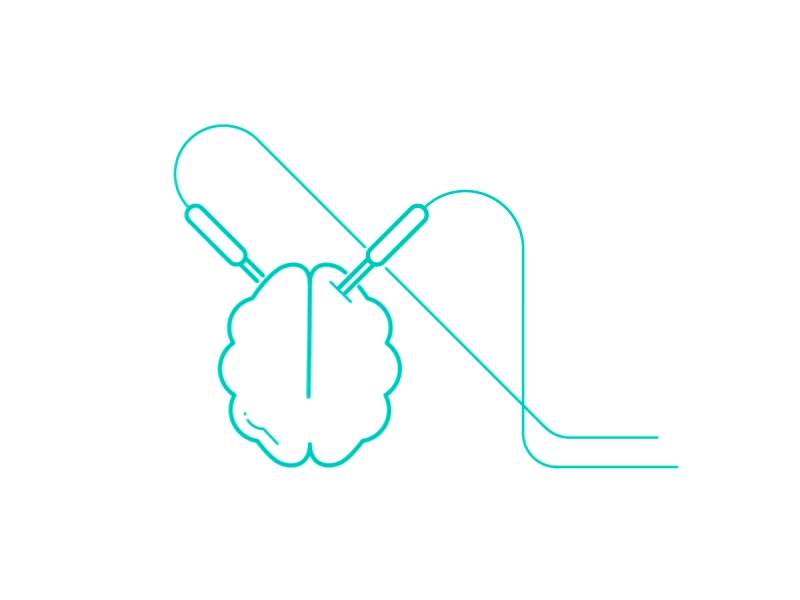

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\Olivia Tween\Desktop\Olivia\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false ;
Deci.DCom               = false ; 
Deci.GCom               = false ; % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\Olivia Tween\Desktop\Olivia\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions 

% Trial definition infomaton                                                                 % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Type =      'ABProb_Polymerase'; %comment out for any new subjects
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52] [53]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.Static = [21 23];
Deci.DT.Displace.Markers = {[31 32] [51 52]};
Deci.DT.Displace.Duration =2;
Deci.DT.Displace.Num = -1;
%Displace will add a new marker of .Num*1000 + displaced trial marker

Deci.DT.Block.Markers   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.bpfreq = [1 30];
Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [2 1];

Deci.Art.AddComponents =  false;

## 4. Analysis

if Deci.Step > 3
    Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52] [1031 1032] [1051 1052] [2031 2032] [2051 2052]};                    
end

AnalysisTypes = {'ABProb_Connectivity'};

AnalysisList = [true ];


## 5. Plotting

## ** 6. Run**

Running Deci for 9 subjects
 


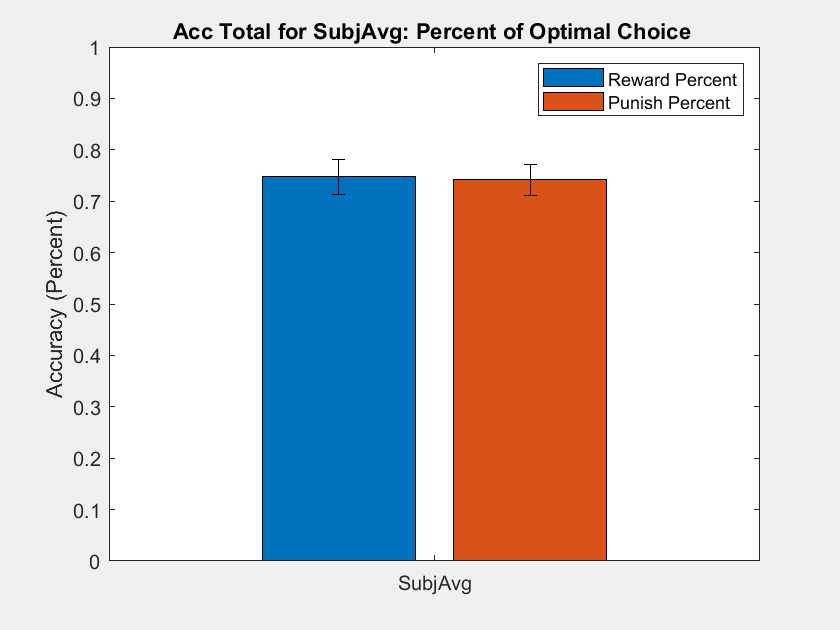

Acc Total for SubjAvg Percent of Optimal Choice 74.7099% +- 3.3289
Acc Total for SubjAvg Percent of Optimal Choice 74.1642% +- 2.9854


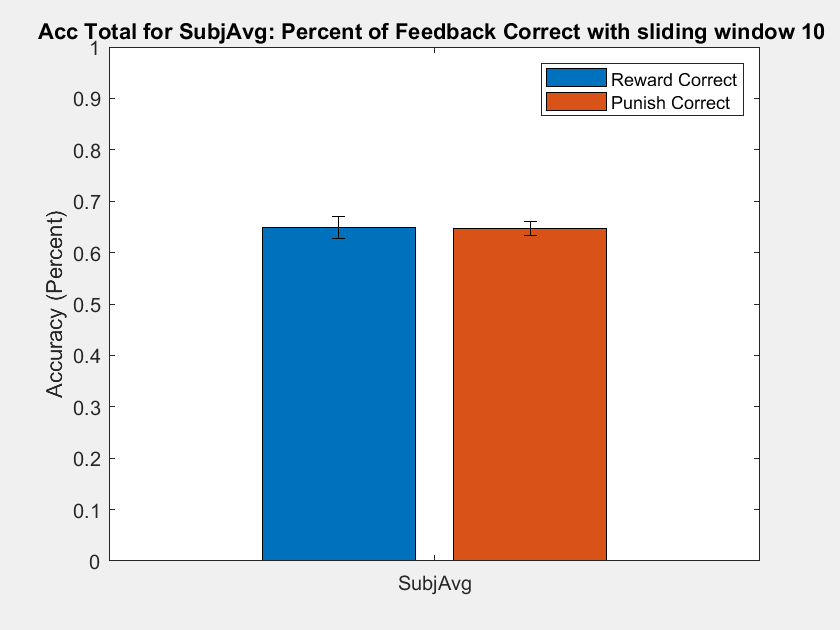

Acc Total for SubjAvg Percent of Feedback Correct with sliding window 10 64.8147% +- 2.1201
Acc Total for SubjAvg Percent of Feedback Correct with sliding window 10 64.6891% +- 1.3658


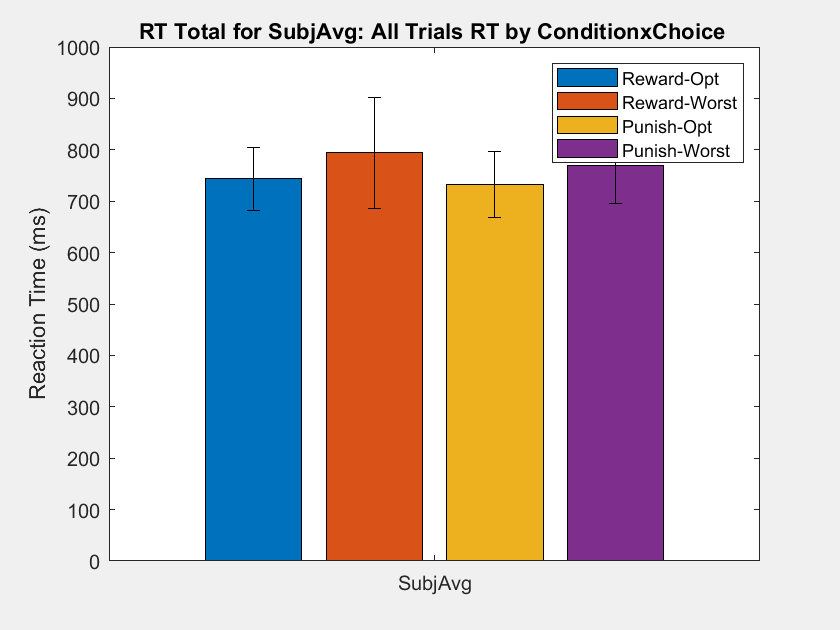

RT Total for SubjAvg Reward-Opt 743.4273 +- 60.7946
RT Total for SubjAvg Reward-Worst 793.8966 +- 107.1993
RT Total for SubjAvg Punish-Opt 732.2134 +- 63.5959
RT Total for SubjAvg Punish-Worst 770.1686 +- 75.1472


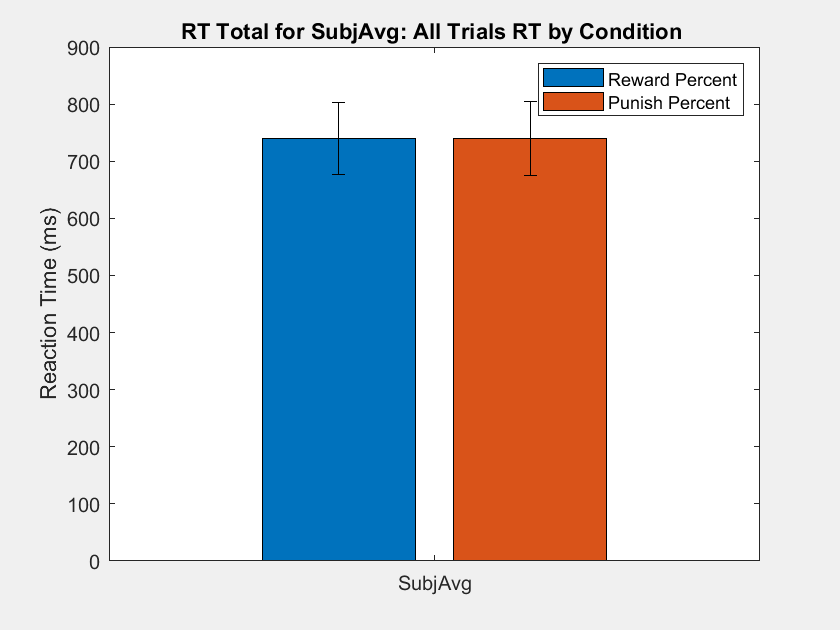

RT Total for SubjAvg Reward Percent 739.725 +- 63.7229
RT Total for SubjAvg Punish Percent 739.2721 +- 64.6618


if Deci.Step == 4
    for AnalysisLocks = find(AnalysisList)
        Deci_Wavelet;
        
        Deci.Analysis.Freq.foi           = exp(linspace(log(3),log(60),40));                           % Frequency of Interest
        Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));                                                         % Width

        
        eval(AnalysisTypes{AnalysisLocks})
        Deci.SubjectList        = 'gui';
        Deci.Analysis.Freq.do  = false;
        Deci.Analysis.ERP.do  = false;
        Deci_Backend(Deci);
        
    end
else
    
    ABProb_SRF;
   
    Deci.Run.Behavior = false;
    Deci.Run.Freq =false;
    Deci.Run.ERP =false;
    Deci.Run.Extra = false; % for model, double, triplet, 2std
   
    Deci.Plot.BslRef =  'Fdb Onset';
    Deci.Plot.Lock =  'Fdb Onset';
    Deci.Plot.FreqYScale = 'linear';
    
    Deci.Plot.GrandAverage = true;
    
    Deci.Plot.Topo.do    =false;
    Deci.Plot.Topo.Foi     = [4 7.5];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [-.5 1.5];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Square.do  =true;
    Deci.Plot.Square.Foi     = [15 35];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [];                   % Time of Interest
    Deci.Plot.Square.Channel = {'FCz'};                % Channel of Interest
    
    Deci.Plot.Wire.do    =false;
    Deci.Plot.Wire.Foi     =   [3 inf];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [-.5 1.5];                   % Time of Interest
    Deci.Plot.Wire.Channel = ['Reinhart-All'];              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Foi     = [13 30];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     = [-.5 1.5];                   % Time of Interest
    Deci.Plot.Bar.Channel =  ['Reinhart-All'];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        %Deci.Plot.Bsl     = [-.5 -.3];
        Deci.Plot.Bsl     = [-.250 -.050];
    else
        %Deci.Plot.Bsl     = [-.5 0];
        Deci.Plot.Bsl     = [-.2 0];
    
    end
  
    if strcmpi(Deci.Plot.Freq.Type,'ITPC')
    Deci.Plot.Freq.Roi = 'maxmin';
    end
    
    if  Deci.Plot.Square.do
        Omnibus = false;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType = 'db';
            Deci.Plot.Stat.Type = 'Randomize Permutation';
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
            Deci.Plot.Stat.correctm = 'fdr';
        end
        Deci.Plot.Stat.FPlots =  false;
    end
    
    if Deci.Plot.Topo.do
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
        end
    end
    
    if Deci.Plot.Bar.do
        Deci.Plot.Stat.do = true;
    end
    
    if Deci.Plot.Wire.do
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  true;
            Deci.Plot.Stat.correctm = 'fdr';
    end
    
    if Deci.Run.Extra
        Deci.Plot.BslType ='none';
    end
    
    Deci_Backend(Deci);
end